# Helicopter performance calculation.

## You need f calculated with McCormick's method.


clc; clear all; close all;

## Data

h = 5000;                                   % Altitude [ft]
v_tas = 30;                                 % true airspeed [kts]
[T,a,P,rho,mu,nu] = atmo(h);                % using function to find density, i.e. rho = 0.00230812 slugs/cu.ft @ SL
w_o = 1800;                                 % weight [lbs]
f = 1.38;                                   % flat plate area [sq.ft]
d_rotor = 5.46;                             % rotor diameter [ft]
r_rotor = d_rotor/2;                        % rotor radius [ft]
c_rotor = 0.5;                              % chord of the rotor [ft]
M_tip = 0.42;                               % rotor tip speed [ft/s]
b_rotor = 3;                                % number of blades in each rotor 
p_avail = 355.2;                            % Power avialable [HP] (source: https://en.wikipedia.org/wiki/Bell_UH-1_Iroquois) 
v_kts = [0:1:150];                          % defining range of TAS [kts]
n_rotor = 8;                                % number of rotors

## Assumptions

## Computation

v_tip = M_tip * a;                              % rotor tip speed [ft/s]
RPM = (v_tip*60) / (2*d_rotor*pi^2);            % rotational speed of the rotor [RPM]
% A_rotor = (pi*r_rotor^2)*n_rotor;               % area of the rotor (sq.ft)

p_avail = p_avail / n_rotor;                    % power available of each rotor [HP]
w_o = w_o / n_rotor;                            % assumed weight lifted by each rotor [lbs]
A_rotor = (pi*r_rotor^2);                       % area of each rotor (sq.ft)

s = (b_rotor*c_rotor)/(pi*r_rotor);             % rotor blade solidity
v_fps = v_kts .* (6080/3600);                   % range of TAS [kts]
D_helo = 0.5 * rho * v_fps.^2 * f;              % parasitic drag [lb]
for x = 1:1:(size(v_fps,2))
    y = x;
    AoA_disk = -asin(D_helo(y)/w_o);            % angle of attack of rotor plane
    if y == 1
        wash_i = sqrt((w_o)/(2*rho*A_rotor));   % calculating intial downwash
    else
        e = 1;
      while e > 0.1 
            wash = wash_i;
            v_bar = sqrt((wash-v_fps(y)*sin(AoA_disk))^2+(v_fps(y)*cos(AoA_disk))^2);
            wash_i = (w_o)/(2*rho*A_rotor*v_bar);
            e = abs(wash-wash_i);
      end
    end
    P_heli_para(y) = 0.5 * rho * v_fps(y)^3*f/550;
    P_heli_induced(y) = 1.15*(w_o)*wash_i/550;
    C_T = (w_o) / (rho * A_rotor * v_tip^2);
    mu = v_fps(y) / v_tip;                      % ratio of forward speed to rotor tip speed
    C_l = 6 * C_T / ( s * (1+(3*mu^2/2)));
    C_d = 0.008 + 0.008 * C_l^2;
    P_heli_profile(y) = (rho*A_rotor*v_tip^3) * ((s*C_d)/8)*(1+3*mu^2)/550;
    P_heli_total(y) = P_heli_para(y) + P_heli_induced(y) + P_heli_profile(y);
end

## Plotting

C_l

C_l = 0.5216

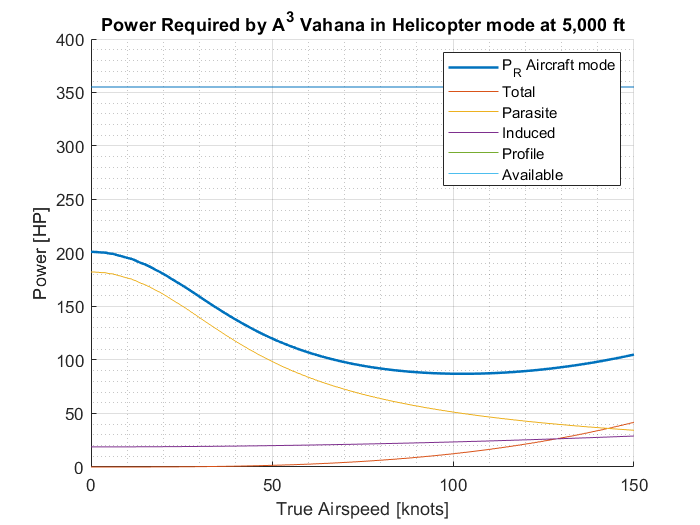


P_heli_para = P_heli_para;
P_heli_induced = P_heli_induced * n_rotor;
P_heli_profile = P_heli_profile * n_rotor;
P_heli_total = P_heli_para + P_heli_induced + P_heli_profile;
p_avail = p_avail * n_rotor;

% Preqd_AC=[113.2035331, 85.44476941, 69.27029381, 59.11100574, 52.62263229, 48.67021092, 46.65625036, 46.25199499, 47.27527224, 49.62941635, 53.27038114, 58.18794728, 64.39444667];
% Vkts_AC=[30, 40, 50, 60, 70, 80, 90, 100, 110, 120, 130, 140, 150];


figure
%plot(Vkts_AC, Preqd_AC, '--','linewidth', 1.5)
hold on
plot(v_kts,P_heli_total,'linewidth',1.5)
hold on 
plot(v_kts,P_heli_para)
hold on 
plot(v_kts,P_heli_induced)
hold on
plot(v_kts,P_heli_profile)
hold on
title('Power Required by A^3 Vahana in Helicopter mode at 5,000 ft')
P_avail = ones(size(v_fps,2)) * p_avail;
plot(v_kts,P_avail)
legend('P_R Aircraft mode','Total','Parasite','Induced','Profile','Available')
grid on
grid minor
xlabel('True Airspeed [knots]')
ylabel('Power [HP]')